## Лабораторная работа №5 & 6

### Задание: для частицы массой m0 в 1dПЯ с бесконечно высокими стенками при x = 0 и x = L = 101А постройте аналитическими и численными Np = 100 методами распределение плотности вероятности для n = 1 и n = 25

P.S. 100 точек оказалось маловато для построения 25-ого уровня, поэтому изначально бралась 1000 точек. Вычислительные мощности позволяют.

clc; clear;
load('constants2.mat');
n = 1000;
e = ones(n,1);
L = 100e-10;
t = hbar ^ 2 / (2 * m0) / (L / n) ^ 2;

Здесь задаём начальные значения. 

m0 берется из файла с константами (т.е. под частицей понимается электрон).


$$t=-\frac{\hbar^2 }{2m_0 \;\Delta x^2 }$$


Минус у t в дальнейшем будет игнорироваться, т.к. при построении матрицы он учитывается.

en = e * t;

Избавляемся от лишних вычислений, сразу просчитываем единичный вектор, умноженный на t

U = 0;
H = full(spdiags([ - en, en * 2 + U, - en], -1:1, n, n));

Потенциальную энергию можно взять примерно -21 порядка, иначе волна взлетает выше птиц.

Здесь строим трёх диагональную матрицу согласно трёхточечной аппроксимации, сразу добавляем диагональ потенциальной энергии.

Метод full() используется для того, разреженную матрицу переопределить как обычную. В ином случае, eig() работает некорректно для данной задачи.

[Psi, Energy] = eig(H);

Т.к. мы используем уравнение вида:


$$H\varphi \left(x\right)=E\varphi \left(x\right),H-\mathrm{гамильтониан}\ldotp$$


Нам необходимо получить две матрицы. Матрица Psi содержит столбцы, каждый из которых является вектором - решением данного уравнения. 

Матрица Energy является квадратной с диагональю, расположенными на ней собственными числами, являющимися энергией каждого уровня (т.е. E(n) = Energy(n, n) ).

Psy_analitical = @(n,a,x) sqrt(2/a) * sin(pi * n * x / a);
Energy_analitical = @(n,a) pi ^ 2 * hbar ^ 2 * n .^ 2 / 2 / m0 / a ^ 2;

Задаём анонимные функции для проверки полученных значений.

Сравним энергии:

level = 1;
fprintf('Для %d уровня энергия равняется %dДж (аналитический)', level, Energy_analitical(level, L + 1e-10));

Для 1 уровня энергия равняется 5.899556e-22Дж (аналитический)

fprintf('Для %d уровня энергия равняется %dДж (численный)', level, Energy(level, level));

Для 1 уровня энергия равняется 6.006114e-22Дж (численный)

То же самое провернём для 25ого уровня:

level = 25;
fprintf('Для %d уровня энергия равняется %dДж (аналитический)', level, Energy_analitical(level, L + 1e-10));

Для 25 уровня энергия равняется 3.687222e-19Дж (аналитический)

fprintf('Для %d уровня энергия равняется %dДж (численный)', level, Energy(level, level));

Для 25 уровня энергия равняется 3.751899e-19Дж (численный)

Построим график для наглядности:

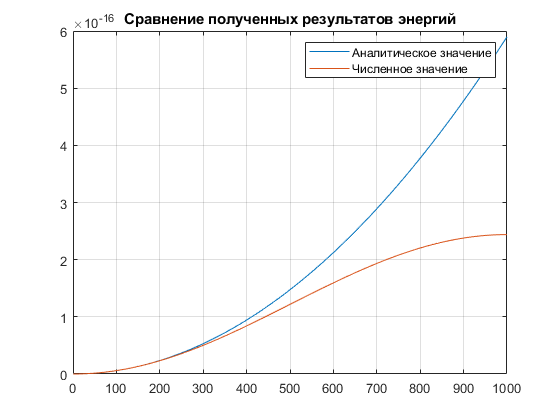

x = linspace(1, n, n);
plot(x, Energy_analitical(x, L + 1e-10));   hold on;
plot(x, diag(Energy));     hold off;      grid on;
title('Сравнение полученных результатов энергий');
legend("Аналитическое значение", "Численное значение");

Как мы видим, для уровней, вплоть до 250, отклонения малозаметны.

Построим плотности вероятности аналогичным способом:

Сначала для 1ого уровня:

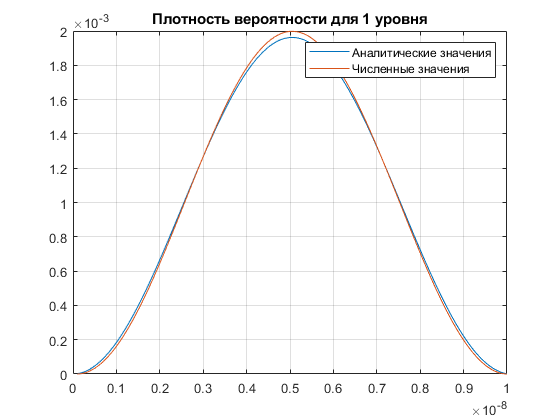

level = 1;
x = linspace(1e-10, L, 1000);
Y = Psy_analitical(level, L + 1e-10, x) .^ 2;
Y = Y / sum(Y);
plot(x, Y);     hold on;
plot(x, Psi(:, level) .^ 2); hold off; grid on;
title("Плотность вероятности для 1 уровня");
legend('Аналитические значения', 'Численные значения');

Моя любимая часть: ctrl+c, ctrl+v для 25ого уровня.

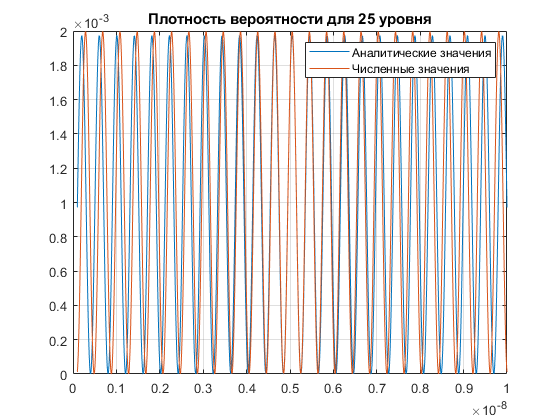

level = 25;
x = linspace(1e-10, L, 1000);
Y = Psy_analitical(level, L + 1e-10, x) .^ 2;
Y = Y / sum(Y);
plot(x, Y);     hold on;
plot(x, Psi(:, level) .^ 2); hold off; grid on;
title("Плотность вероятности для 25 уровня");
legend('Аналитические значения', 'Численные значения');

Как мы видим, графики достаточно близки друг к другу. При увеличении энергетического уровня, а, соответственно и энергии, растёт равномерность вероятности нахождения частицы по всей яме.

#### Вывод: при сравнении аналитических и численных графиков проявляются расхождения. Для плотности вероятности это по большей части связано с выбором точек на координатной оси. Для энергий, в зависимости от уровня, разногласия наступают примерно на 20% от максимального значения абциссы. Связано с погрешностями 